UHF = 400e6; %Hz
Sband = 2.3e9; %Hz
Xband = 8.4e9; %Hz
Kband = 32e9; %Hz
Vband = 60e9; %Hz

S_orbit = 1300e3; %m
S_earth = 11.2*1.496e11; %m

glider = dictionary("P",5,"D",0.5,"eta",0.55,"Ll",0.9,"f",Xband,"T",200,"R",1e6,"La",-1);
lander = dictionary("P",75,"D",1,"eta",0.7,"Ll",0.9,"f",Xband,"T",200,"R",1e6,"La",-1);
orbiter = dictionary("P",50,"D",1.5,"eta",0.7,"Ll",0.9,"f",Kband,"T",600,"R",1e3,"La",0);
DSN = dictionary("D",70,"eta",0.8,"La",-0.5);

c = 299792458; %m/s
k = 1.38e-23; %J/K
Ls = @(S,f) 20*log10(c) - 20*log10(4*pi) - 20*log10(S) - 20*log10(f); %dB
G = @(D,eta,f) 10*log10(pi^2*eta*D^2*f^2/c^2); %dBi
G(glider("D"),glider("eta"),glider("f"))

ans = 30.2752


SNR = @(trans, rec, dist) 10*log10(trans("P")) + 10*log10(trans("Ll")) + G(trans("D"),trans("eta"),trans("f")) + Ls(dist,trans("f")) + trans("La") + rec("La") + G(rec("D"),rec("eta"),trans("f")) - 10*log10(k) - 10*log10(trans("T")) - 10*log10(trans("R"));
fprintf("Primary\n");

Primary


fprintf("Glider to Lander SNR: %.2f dB\n", SNR(glider,lander,100e3));

Glider to Lander SNR: 66.81 dB


fprintf("Lander to Orbiter SNR: %.2f dB\n", SNR(lander,orbiter,S_orbit));

Lander to Orbiter SNR: 67.88 dB


fprintf("Orbiter to DSN SNR: %.2f dB\n", SNR(orbiter, DSN, S_earth));

Orbiter to DSN SNR: 18.74 dB


fprintf("Alternate\n");

Alternate


lander("R") = 800;
fprintf("Glider to Lander SNR: %.2f dB\n", SNR(glider,lander,100e3));

Glider to Lander SNR: 66.81 dB


fprintf("Lander to DSN SNR: %.2f dB",SNR(lander,DSN,S_earth));

Lander to DSN SNR: 10.10 dB

fprintf("Contingency\n");

Contingency


fprintf("Glider to Orbiter SNR: %.2f dB\n",SNR(glider,orbiter,S_orbit));

Glider to Orbiter SNR: 49.05 dB


fprintf("Orbiter to DSN SNR: %.2f dB",SNR(orbiter,DSN,S_earth));

Orbiter to DSN SNR: 18.74 dB

fprintf("Emergency\n")

Emergency


glider("R") = 1;
fprintf("Glider to DSN SNR: %.2f dB",SNR(glider,DSN,S_earth));

Glider to DSN SNR: 20.31 dB

h = 1300e3; %m
G = 6.67430e-11; %N-m^2/kg^2
M = 1.3452e23; %kg
R = 2575e3; %m
mu = G*M; %N-m^2/kg

v = sqrt(mu/(h + R)); %m/s
theta = asin(sqrt((R + h)^2 - R^2)/(R + h)); %rad
s = (R + h)*2*theta; %m
t = s/v; %s
t/60 %min

ans = 71.6155

t*lander("R")/1e6 %Mb

ans = 3.4375

P = 2*pi*(R + h)/v %s

P = 1.5995e+04

P/3600 %hr

ans = 4.4431

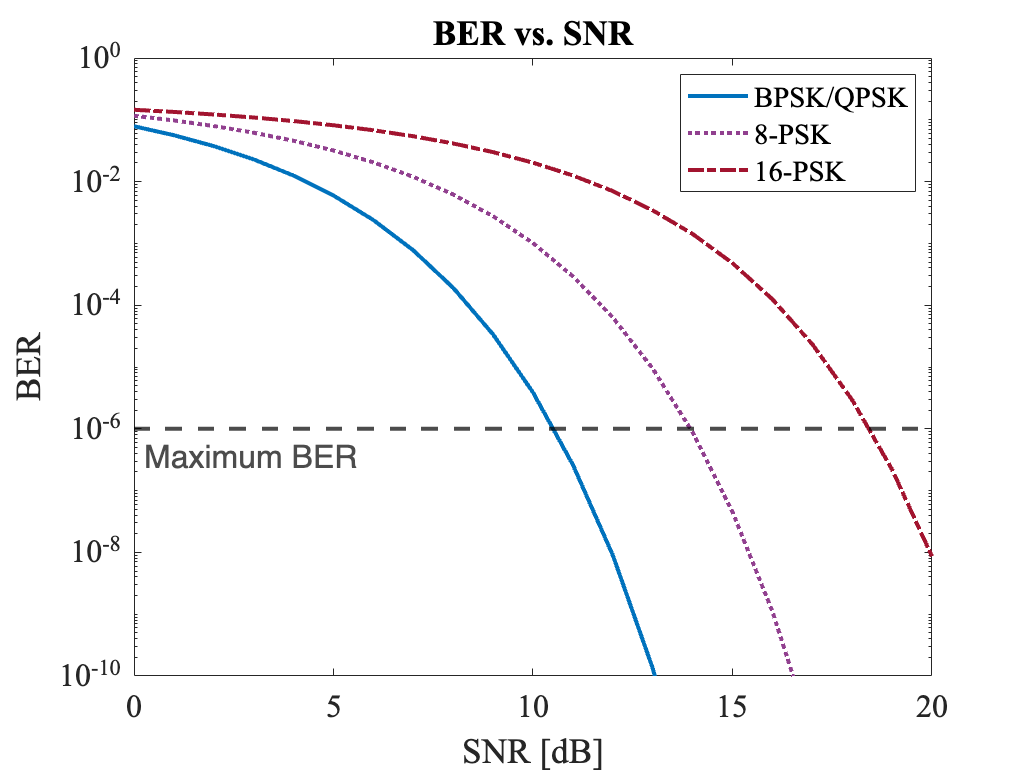

BER = [
    0	1.000	7.865E-02	7.865E-02	1.162E-01	1.453E-01;
    1	1.259	5.628E-02	5.628E-02	9.764E-02	1.340E-01;
    2	1.585	3.751E-02	3.751E-02	7.932E-02	1.218E-01;
    3	1.995	2.288E-02	2.288E-02	6.183E-02	1.089E-01;
    4	2.512	1.250E-02	1.250E-02	4.579E-02	9.546E-02;
    5	3.162	5.954E-03	5.954E-03	3.184E-02	8.162E-02;
    6	3.981	2.388E-03	2.388E-03	2.048E-02	6.773E-02;
    7	5.012	7.727E-04	7.727E-04	1.195E-02	5.418E-02;
    8	6.310	1.909E-04	1.909E-04	6.181E-03	4.143E-02;
    9	7.943	3.363E-05	3.363E-05	2.748E-03	2.998E-02;
    10	10.000	3.872E-06	3.872E-06	1.011E-03	2.025E-02;
    11	12.589	2.613E-07	2.613E-07	2.937E-04	1.256E-02;
    12	15.849	9.006E-09	9.006E-09	6.338E-05	7.010E-03;
    13	19.953	1.333E-10	1.333E-10	9.417E-06	3.427E-03;
    14	25.119	6.810E-13	6.810E-13	8.756E-07	1.421E-03;
    15	31.623	9.124E-16	9.124E-16	4.516E-08	4.789E-04;
    16	39.811	2.267E-19	2.267E-19	1.110E-09	1.246E-04;
    17	50.119	6.759E-24	6.759E-24	1.073E-11	2.342E-05;
    18	63.096	1.396E-29	1.396E-29	3.210E-14	2.925E-06;
    19	79.433	1.001E-36	1.001E-36	2.192E-17	2.187E-07;
    20	100.000	1.044E-45	1.044E-45	2.332E-21	8.573E-09;
];
fig = figure();
hold on
pl1 = plot(BER(:,1),BER(:,3));
pl1.LineWidth = 2;
pl1.DisplayName = "BPSK/QPSK";
pl1.LineStyle = "-";
pl1.Color = "#0072bd";
pl2 = plot(BER(:,1),BER(:,5));
pl2.LineWidth = 2;
pl2.DisplayName = "8-PSK";
pl2.LineStyle = ":";
pl2.Color = "#91408f";
pl3 = plot(BER(:,1),BER(:,6));
pl3.LineWidth = 2;
pl3.DisplayName = "16-PSK";
pl3.LineStyle = "-.";
pl3.Color = "#a2142f";
ax = gca;
ax.FontName = "Times New Roman";
ax.FontSize = 16;
ax.YScale = "log";
ax.YLim = [1e-10 1];
ax.XLim = [0 20];
box(ax,"on");
title(ax,"BER vs. SNR");
ylabel(ax,"BER");
xlabel(ax,"SNR [dB]");
yl = yline(1e-6);
yl.Label = "Maximum BER";
yl.LineWidth = 2;
yl.LineStyle = "--";
yl.Color = "#000000";
yl.LabelVerticalAlignment = "bottom";
yl.LabelHorizontalAlignment = "left";
yl.FontSize = 16;
yl.LabelOrientation = "aligned";
legend([pl1 pl2 pl3]);